**1. Considere duas variáveis aleatórias com a seguinte distribuição conjunta:**

**(a)** Calcule as funções de massa de probabilidade marginais de X e Y e represente-as graficamente;

P = [0.3, 0.2, 0;
     0.1, 0.15, 0.05;
     0, 0.1, 0.1]

P =     0.3000    0.2000         0
    0.1000    0.1500    0.0500
         0    0.1000    0.1000



x = [0 1 2];
y = [0 1 2];


Px = sum(P, 2)'

Px =     0.5000    0.3000    0.2000



Py = sum(P, 1)

Py =     0.4000    0.4500    0.1500


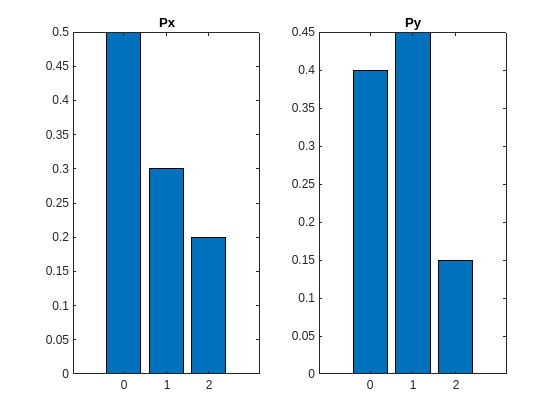


subplot(1, 2, 1);
bar(x, Px);
title('Px');

subplot(1, 2, 2);
bar(y, Py);
title('Py');

**(b)** Calcule a média e variância de X e Y;

media_x = sum(x.*Px)

media_x = 0.7000

media_y = sum(y.*Py)

media_y = 0.7500


var_x = sum((x - media_x).^2 .* Px)

var_x = 0.6100

var_y = sum((y - media_y).^2 .* Py)

var_y = 0.4875

**(c)** Calcule a correlação, covariância e coeficiente de correlação entre X e Y

cov_xy = 0;
for i = 1:3
    for j = 1:3
        cov_xy = cov_xy + (x(i) - media_x) * (y(j) - media_y) * P(i,j);
    end
end

cov_xy

cov_xy = 0.3250


desvio_x = sqrt(var_x)

desvio_x = 0.7810

desvio_y = sqrt(var_y)

desvio_y = 0.6982


corr_xy = cov_xy / (desvio_x * desvio_y)

corr_xy = 0.5960